# Scattering from a small dielectric sphere

Grids:

clear variables

ps          = .105;                 % pixel size (x,y,z) in object space (microns)
lambda      = 0.5;                  % central wavelength (microns)
NA          = 1.0;                  % numerical aperture of imaging and detection lens
n_imm       = 1;                % refractive index of immersion media
k0=(2*pi)/lambda;
k=k0*n_imm;
c=(3e8)*1e6*1e-15;                  % speed of light microns per fs
N           = 2^9;                  % lateral pixel dimension 
x           = ps*[-N/2:N/2-1];      % 1D axis in x
y=x;
dfx         = 1/(N*ps);             % Fourier spacing of padded axis
[X Y]=meshgrid(x,y);
fx          = dfx*[-N/2:N/2-1];     % 1D axis in fx
[fxx,fyy]   = meshgrid(fx,fx);      % 2D grid in fx/fy

fx          = ifftshift(fx);        % FFT shifting Fourier axes
fxx         = ifftshift(fxx);       % FFT shifting Fourier axes
fyy         = ifftshift(fyy);       % FFT shifting Fourier axes

## Let's look at angular green's functions

Previous way of doing it

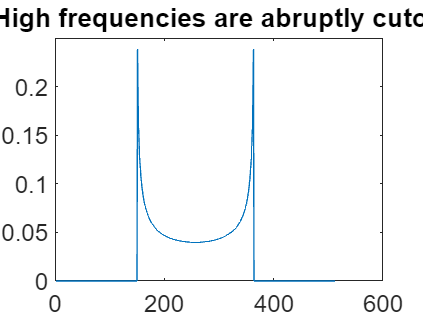

prop_crop           = (fxx.^2 + fyy.^2 > (n_imm/lambda)^2==0);
prop_phs= 1i*2*pi*sqrt((n_imm/lambda)^2-(fxx.^2+fyy.^2));
prop_phs=prop_phs.*prop_crop;
prop=@(z) exp(prop_phs*z);
Mask=(n_imm/lambda)^2>1.01*((fxx.^2+fyy.^2));
AG= ((-1i.*exp(prop_phs.*ps)./(4.*pi.*sqrt((n_imm/lambda)^2-(fxx.^2+fyy.^2))))).*Mask;
AG(isnan(AG)==1)=0;

fftshift(AG);

figure; plot(abs((ans(end/2,:))))
title('High frequencies are abruptly cutoff')

Better way (adding absorption term shifting off the pole)

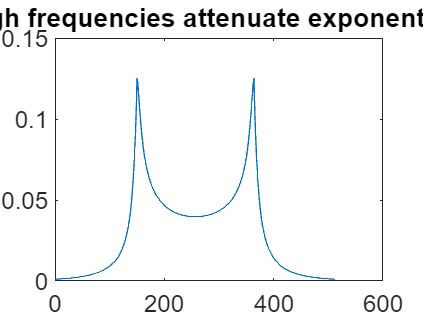

Eps=.002;
SquareRt=@(a) abs(real(sqrt(a)))+1i*abs(imag(sqrt(a))); % making sure imaginary and real part is pos otherwise will get gain or backward propagating field

prop_phs= 1i*2*pi*SquareRt((n_imm/lambda)^2-(fxx.^2+fyy.^2)+1i*Eps); %Add small absorption term to avoid indeterminates in the angular greens function


prop=@(z) exp(prop_phs*z);
%Mask=(n_imm/lambda)^2>1.01*((fxx.^2+fyy.^2));

AG2= ((-1i.*exp(prop_phs.*ps)./(4.*pi.*SquareRt((n_imm/lambda)^2-(fxx.^2+fyy.^2)+1i*Eps*200)))); % Angular Greens function

fftshift(AG2);
figure; plot(abs((ans(end/2,:))))
title('High frequencies attenuate exponentially')

## For really high spatial frequency objects (like a small sphere) we need to make sure that we are attenuating the high spatial frequencies slowly with the greens function. If we don't (such as in the previous method) there will be ringing due to the sharp cutoff which will add energy everywhere in real space

## Let's make a small sphere

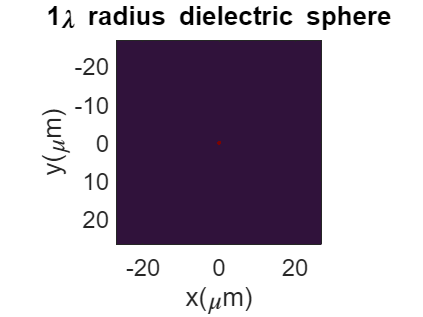

Nz=N;
z           = ps*[-Nz/2:Nz/2-1];
[X3 Y3 Z3]=meshgrid(x,y,z);
nsphere=1.2;
dielectricSphere=X3.^2+Y3.^2+Z3.^2<=lambda^2;
dielectricSphere=double(dielectricSphere)*(nsphere-n_imm)+n_imm;
%dielectricSphere(dielectricSphere==0)=n_imm;
figure; imagesc(x,y,dielectricSphere(:,:,end/2))
xlabel('x(\mum)')
ylabel('y(\mum)')
axis square
title('1\lambda radius dielectric sphere')


V=-(k0)^2*((dielectricSphere).^2-n_imm^2);

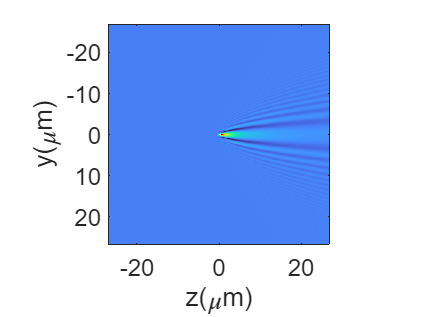

Eps=3.2;
U_inp=ones(N,N);
EvolB=MultiLayerBornv2(fxx,fyy,lambda,n_imm,ps,V,U_inp,Eps,'Vol');%.017
%exp(-2*k0*eps*zz(end))
figure; imagesc(x,z,squeeze(abs(EvolB(end/2,:,:))))
xlabel('z(\mum)')
ylabel('y(\mum)')
axis square

## Looks pretty good! May have to adjust value of Eps depending on type of problem. Also you can see that for this small sphere the light expands fast enough that it is beginning to reach the edge of our window and wrapping around. Will need to add more points to avoid this.